## Module 2 project 9

This 

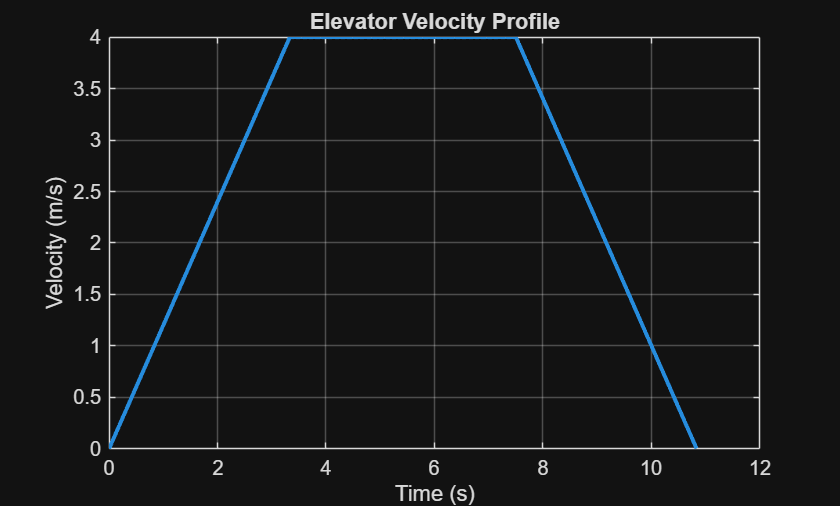

%% Project 9: Elevator Motion Profile
% Parameters
a = 1.2;          % acceleration (m/s^2)
v_cruise = 4;     % cruise speed (m/s)
distance_total = 30; % total travel distance (m)

% Phase durations
t_acc = v_cruise / a;          % time to accelerate
d_acc = 0.5 * a * t_acc^2;     % distance during acceleration
t_dec = t_acc;                 % symmetric
d_dec = d_acc;

% d_cruise may be negative if distance is too short for full cruise
d_cruise = distance_total - (d_acc + d_dec);
t_cruise = d_cruise / v_cruise;

% Time vector
dt = 0.01;
t = 0:dt:(t_acc + t_cruise + t_dec);

% Preallocate velocity
v = zeros(size(t));

%% Piecewise velocity profile
% Build velocity in three phases: accel, cruise, decel (time-aligned)
for i = 1:length(t)
    if t(i) <= t_acc
        % Acceleration phase
        v(i) = a * t(i);
    elseif t(i) <= t_acc + t_cruise
        % Cruise phase
        v(i) = v_cruise;
    else
        % Deceleration phase
        t_dec_phase = t(i) - (t_acc + t_cruise);
        v(i) = v_cruise - a * t_dec_phase;
    end
end

%% Position via numerical integration
% Integrate velocity to get position (starts at zero)
x = cumtrapz(t, v);

%% Plot velocity
figure;
plot(t, v, 'LineWidth', 2)
xlabel('Time (s)')
ylabel('Velocity (m/s)')
title('Elevator Velocity Profile')
grid on

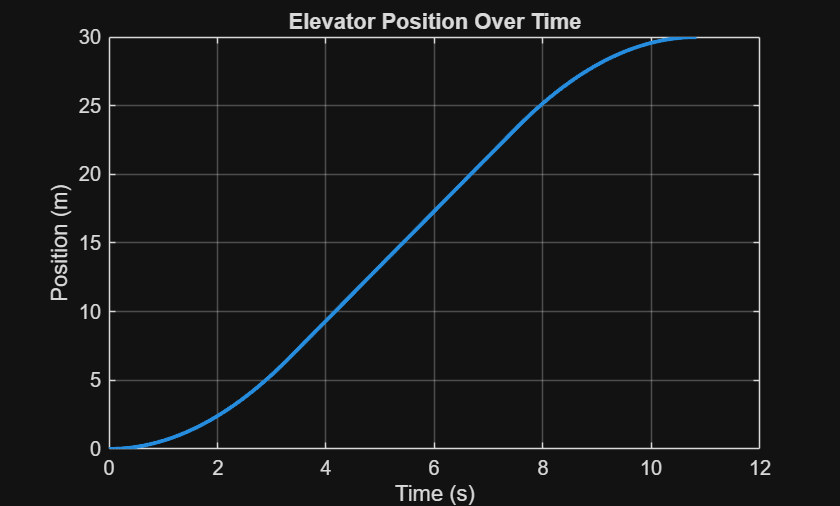


%% Plot position
figure;
plot(t, x, 'LineWidth', 2)
xlabel('Time (s)')
ylabel('Position (m)')
title('Elevator Position Over Time')
grid on